## **Problem 1**

**1.因為他們使用的單位（尺度）不同，使GDP相對於獎牌數、人口數這兩者的變化量不同，而影響了PCA的結果。**

**2.應先對資料進行標準化（standardization）再進行分析。**

## **Problem 2**

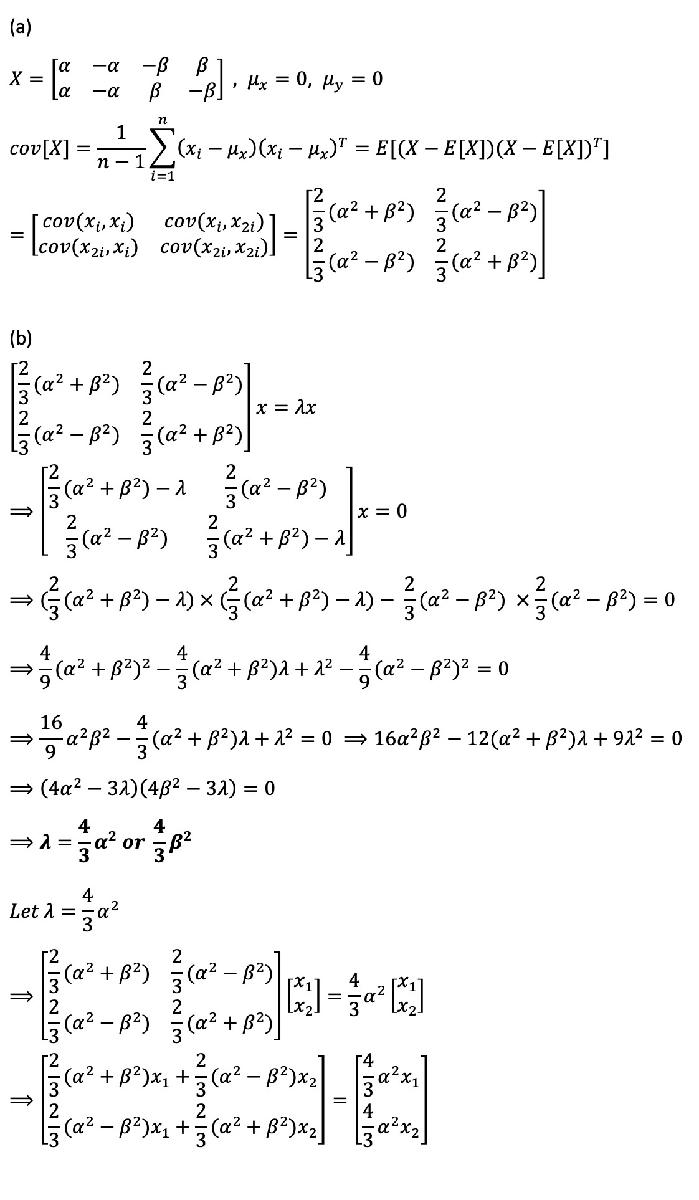

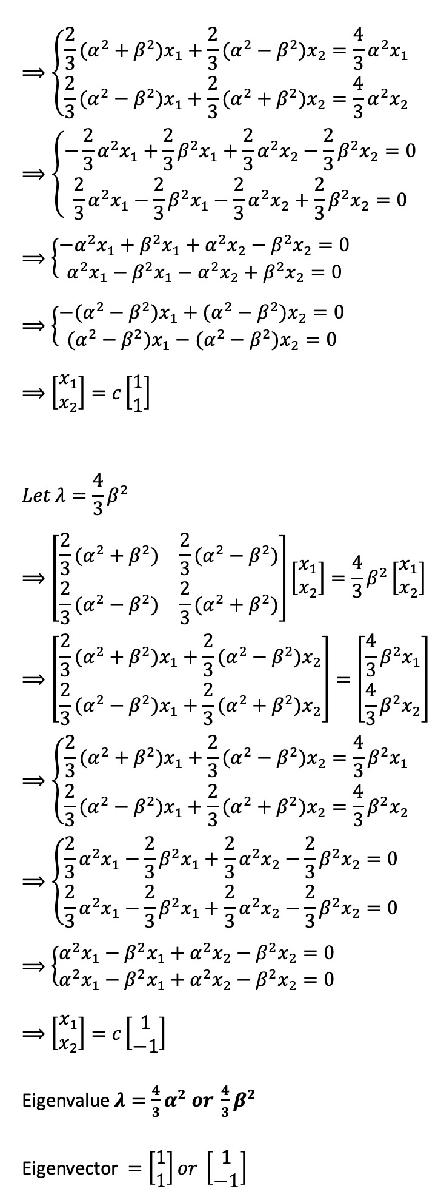

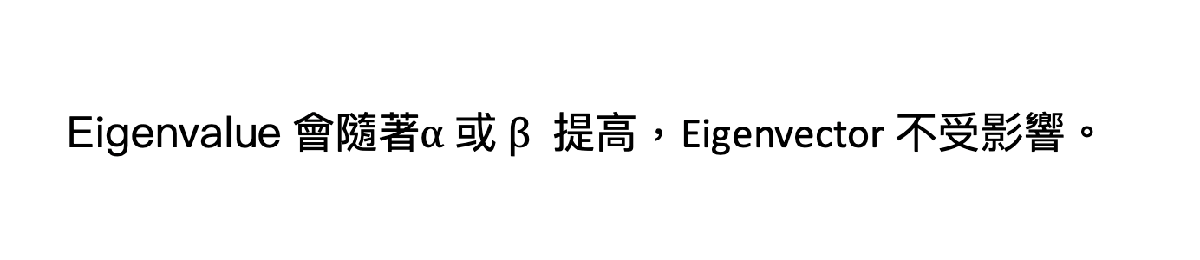

## **Problem 3**

**(a) **Suppose the correct intrinsic dimensionality of the data is 10

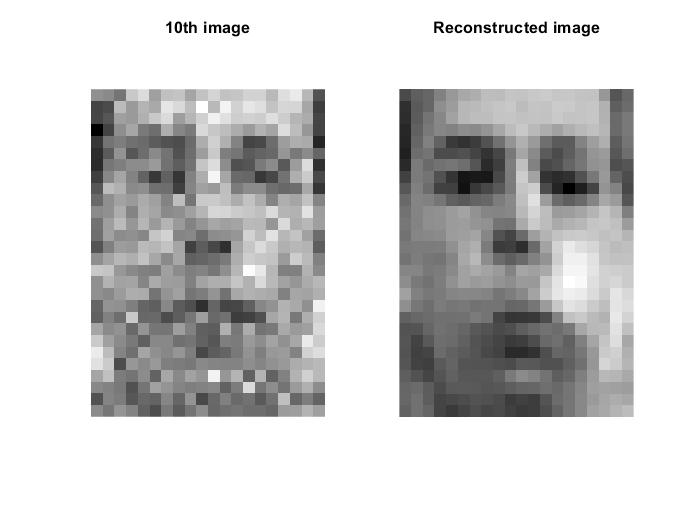

%load data
clear;
load('04HW2_noisy.mat');

%10th image
figure;
I_10=reshape(X(:, 10), 20, 28)';
[U,S,V] = svd(X);
S_rc1 = S;
S_rc1(:,11:560)=0;
X_rc1 = U*S_rc1*V;
I_10rc=reshape(X_rc1(:, 10), 20, 28)';
colormap gray;

subplot(1,2,1);
imagesc(I_10);axis equal; axis off;
title('10th image');
subplot(1,2,2);
imagesc(I_10rc);axis equal; axis off;
title('Reconstructed image');

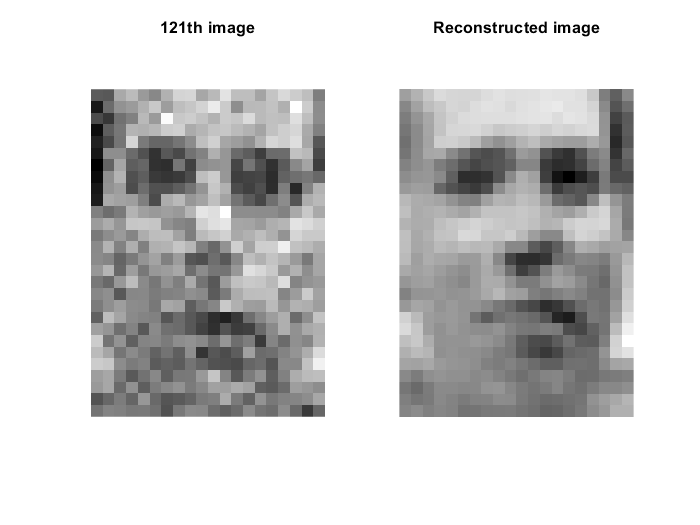

%121th image
figure;
I_121=reshape(X(:, 121), 20, 28)';
I_121rc=reshape(X_rc1(:, 121), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_121);axis equal; axis off;
title('121th image');
subplot(1,2,2);
imagesc(I_121rc);axis equal; axis off;
title('Reconstructed image');

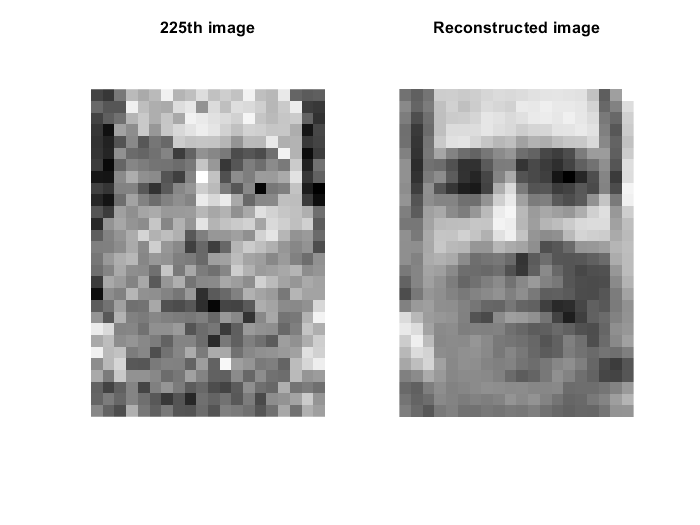


%225th image
figure;
I_225=reshape(X(:, 225), 20, 28)';
I_225rc=reshape(X_rc1(:, 225), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_225);axis equal; axis off;
title('225th image');
subplot(1,2,2);
imagesc(I_225rc);axis equal; axis off;
title('Reconstructed image');

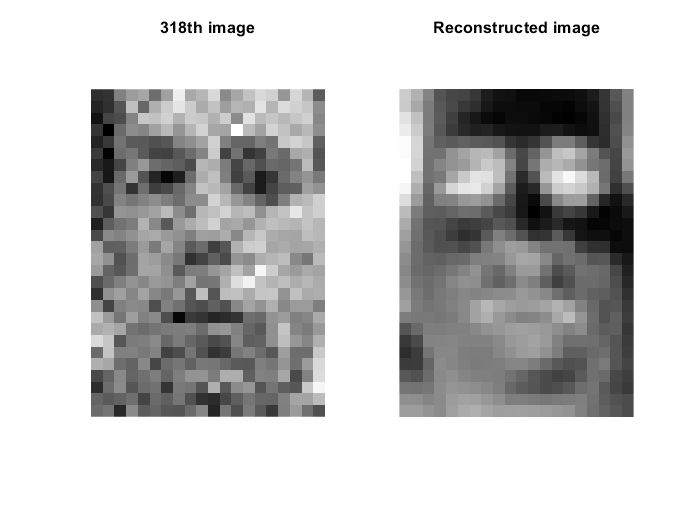

%318th image
figure;
I_318=reshape(X(:, 318), 20, 28)';
I_318rc=reshape(X_rc1(:, 318), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_318);axis equal; axis off;
title('318th image');
subplot(1,2,2);
imagesc(I_318rc);axis equal; axis off;
title('Reconstructed image');

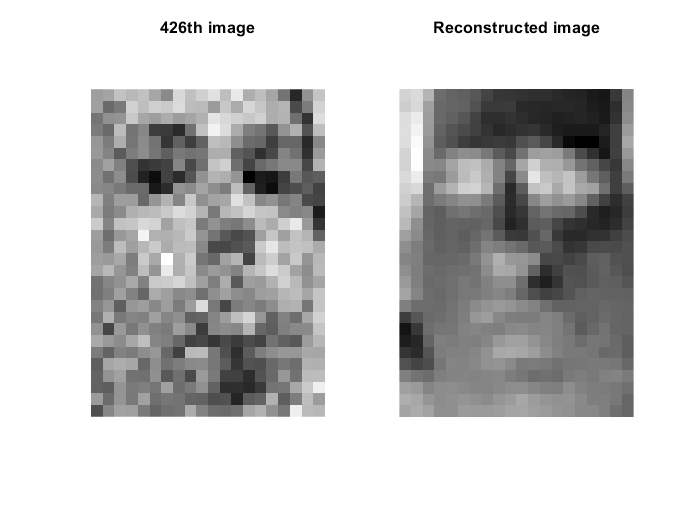


%426th image
figure;
I_426=reshape(X(:, 426), 20, 28)';
I_426rc=reshape(X_rc1(:, 426), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_426);axis equal; axis off;
title('426th image');
subplot(1,2,2);
imagesc(I_426rc);axis equal; axis off;
title('Reconstructed image');

(b)Suppose the correct intrinsic dimensionality of the data is 2

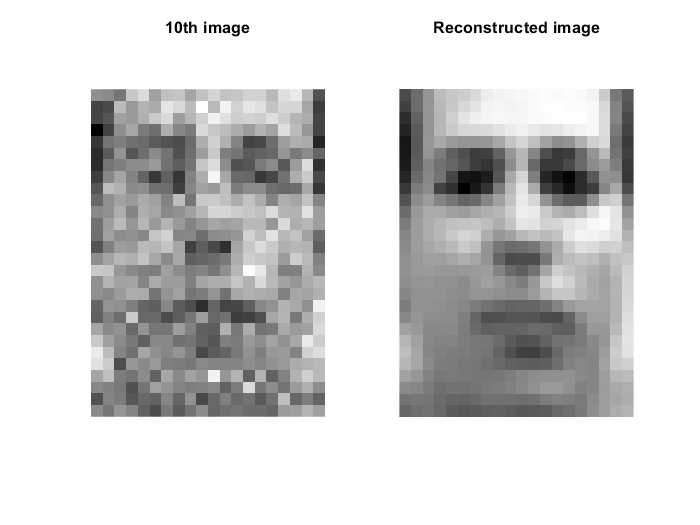

%10th image
figure;
S_rc2 = S;
S_rc2(:,3:560)=0;
X_rc2 = U*S_rc2*V;
I_10rc2=reshape(X_rc2(:, 10), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_10);axis equal; axis off;
title('10th image');
subplot(1,2,2);
imagesc(I_10rc2);axis equal; axis off;
title('Reconstructed image');

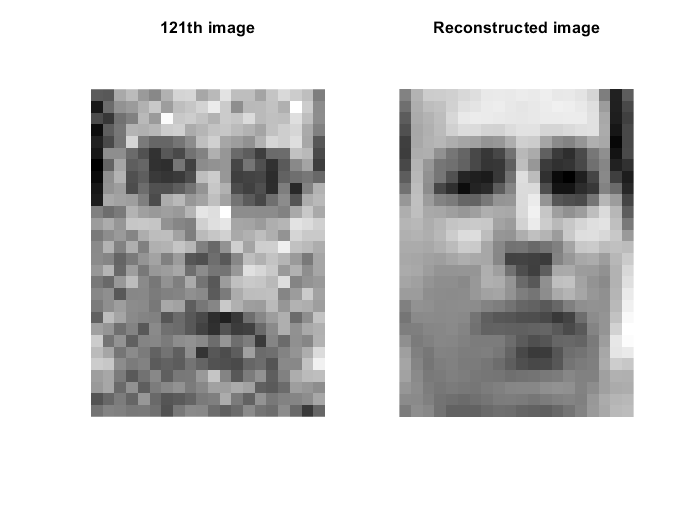

%121th image
figure;
I_121rc2=reshape(X_rc2(:, 121), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_121);axis equal; axis off;
title('121th image');
subplot(1,2,2);
imagesc(I_121rc2);axis equal; axis off;
title('Reconstructed image');

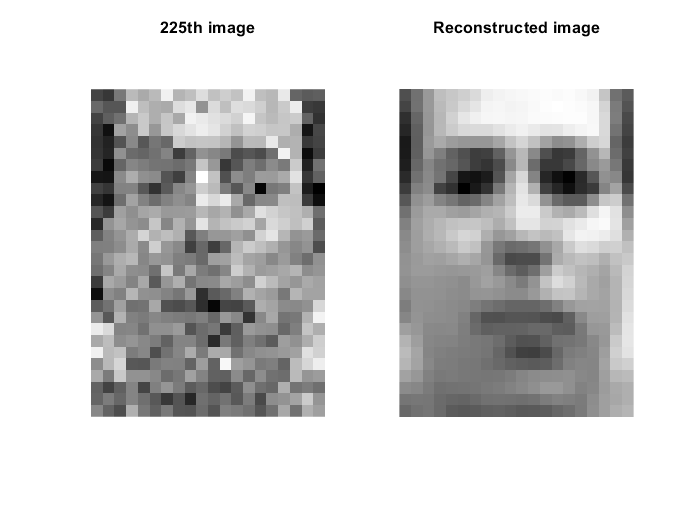

%225th image
figure;
I_225rc2=reshape(X_rc2(:, 225), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_225);axis equal; axis off;
title('225th image');
subplot(1,2,2);
imagesc(I_225rc2);axis equal; axis off;
title('Reconstructed image');

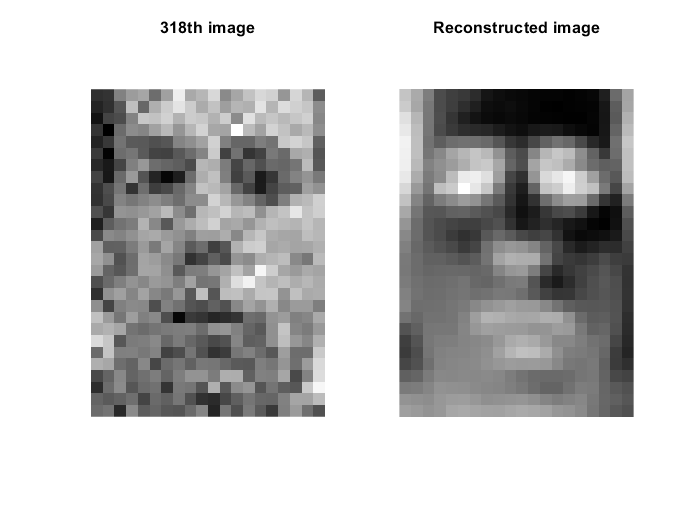


%318th image
figure;
I_318rc2=reshape(X_rc2(:, 318), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_318);axis equal; axis off;
title('318th image');
subplot(1,2,2);
imagesc(I_318rc2);axis equal; axis off;
title('Reconstructed image');

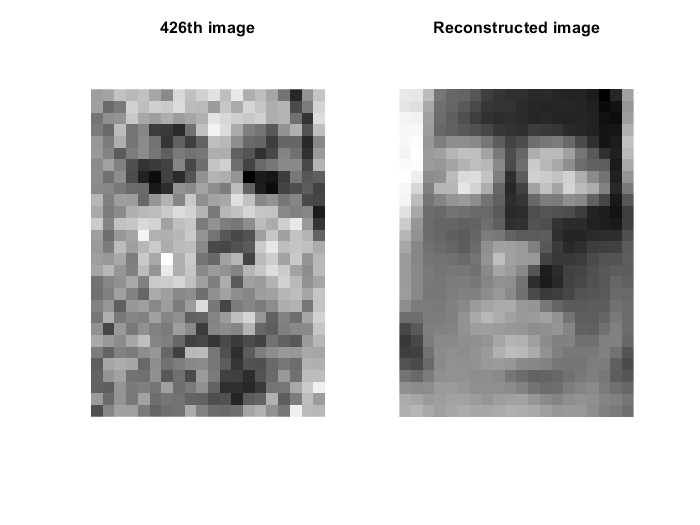


%426th image
figure;
I_426rc2=reshape(X_rc2(:, 426), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_426);axis equal; axis off;
title('426th image');
subplot(1,2,2);
imagesc(I_426rc2);axis equal; axis off;
title('Reconstructed image');

Suppose the correct intrinsic dimensionality of the data is 30

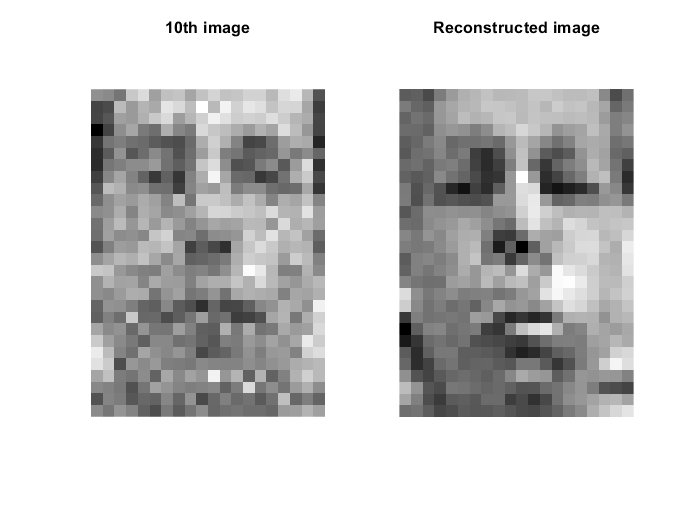

%10th image
figure;
S_rc3 = S;
S_rc3(:,31:560)=0;
X_rc3 = U*S_rc3*V;
I_10rc3=reshape(X_rc3(:, 10), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_10);axis equal; axis off;
title('10th image');
subplot(1,2,2);
imagesc(I_10rc3);axis equal; axis off;
title('Reconstructed image');

%121th image
figure;
I_121rc3=reshape(X_rc3(:, 121), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_121);axis equal; axis off;
title('121th image');
subplot(1,2,2);
imagesc(I_121rc2);axis equal; axis off;
title('Reconstructed image');

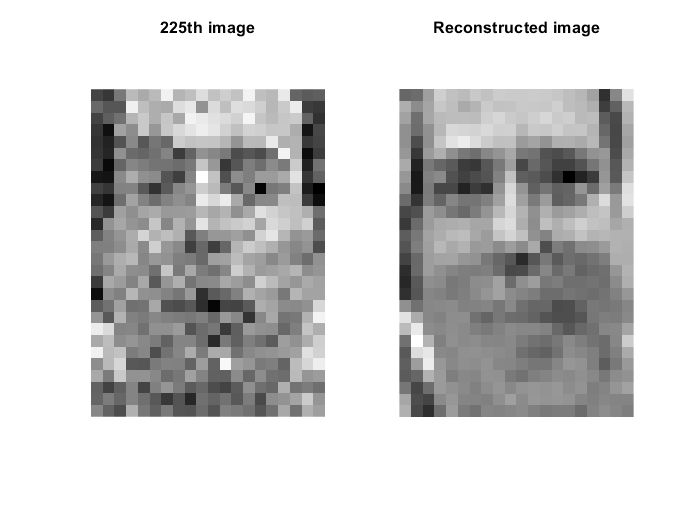

%225th image
figure;
I_225rc3=reshape(X_rc3(:, 225), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_225);axis equal; axis off;
title('225th image');
subplot(1,2,2);
imagesc(I_225rc3);axis equal; axis off;
title('Reconstructed image');

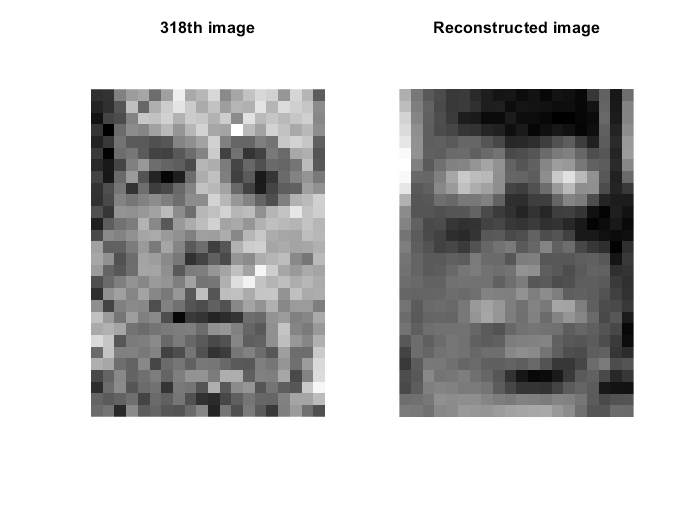


%318th image
figure;
I_318rc3=reshape(X_rc3(:, 318), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_318);axis equal; axis off;
title('318th image');
subplot(1,2,2);
imagesc(I_318rc3);axis equal; axis off;
title('Reconstructed image');

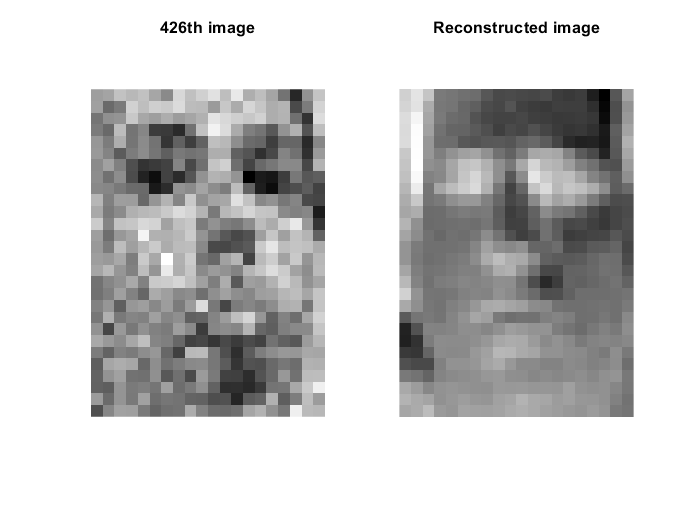


%426th image
figure;
I_426rc3=reshape(X_rc3(:, 426), 20, 28)';
colormap gray;
subplot(1,2,1);
imagesc(I_426);axis equal; axis off;
title('426th image');
subplot(1,2,2);
imagesc(I_426rc3);axis equal; axis off;
title('Reconstructed image');

(c)

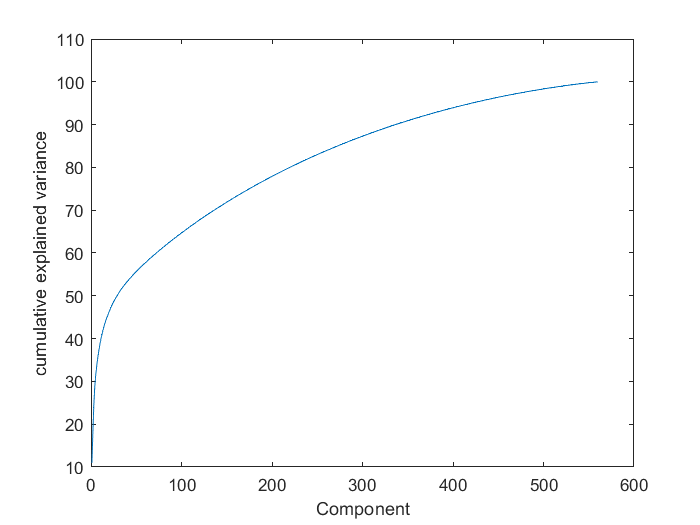

%returns explained, a vector containing the percentage of the total variance explained by each principal component.
covx = cov(X');
[COEFF,latent,explained] = pcacov(covx);

%compute the cumulatie varience
for i = 1:560
    C(i) = sum(explained(1:i));
end
figure;
plot(C);
xlabel('Component'); ylabel('cumulative explained variance');

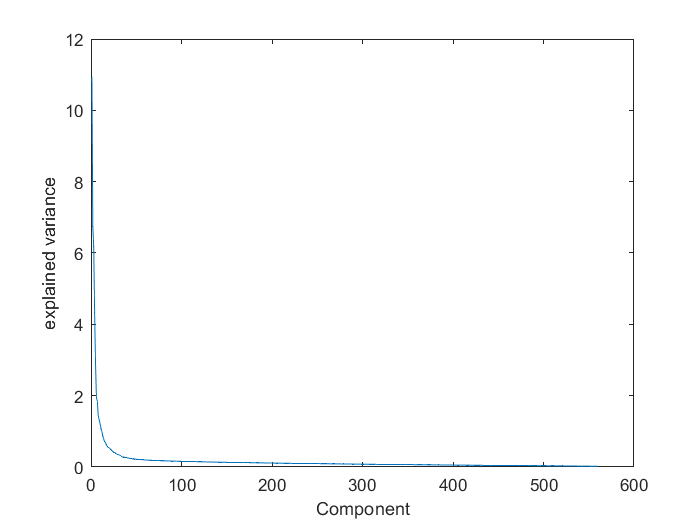

figure;
plot(explained);
xlabel('Component'); ylabel('explained variance');

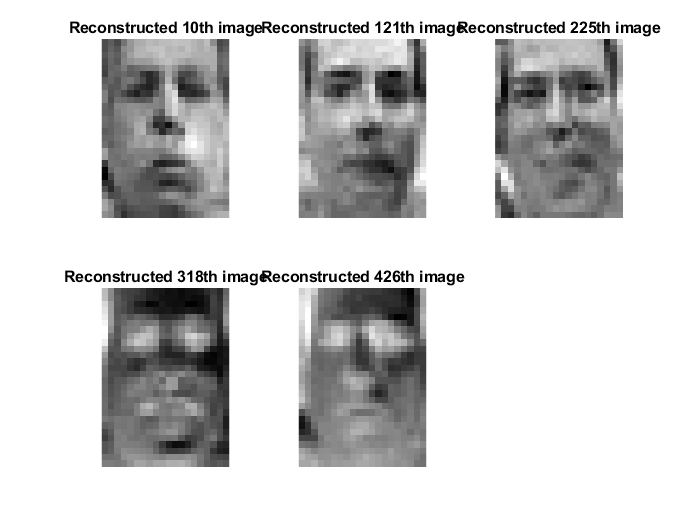


%find the component of explained variance <0.5
for i = 1:560
    if explained(i) < 0.5
        best_d = i-1;
    break;
    end
end


%plot the reconstructed image
figure;
S_rc4 = S;
S_rc4(:,(best_d+1):560)=0;
X_rc4 = U*S_rc4*V;
I_10rc4=reshape(X_rc4(:, 10), 20, 28)';
I_121rc4=reshape(X_rc4(:, 121), 20, 28)';
I_225rc4=reshape(X_rc4(:, 225), 20, 28)';
I_318rc4=reshape(X_rc4(:, 318), 20, 28)';
I_426rc4=reshape(X_rc4(:, 426), 20, 28)';
colormap gray;
subplot(2,3,1);
imagesc(I_10rc4);axis equal; axis off;
title('Reconstructed 10th image');
subplot(2,3,2);
imagesc(I_121rc4);axis equal; axis off;
title('Reconstructed 121th image');
subplot(2,3,3);
imagesc(I_225rc4);axis equal; axis off;
title('Reconstructed 225th image');
subplot(2,3,4);
imagesc(I_318rc4);axis equal; axis off;
title('Reconstructed 318th image');
subplot(2,3,5);
imagesc(I_426rc4);axis equal; axis off;
title('Reconstructed 426th image');

fprintf('best intrinsic dimensionality is %s \ncumulative explained variance percentage = %s',num2str(best_d),num2str(C(i)));

best intrinsic dimensionality is 21 
cumulative explained variance percentage = 47.2779

由component/explained variance圖可發現，explained variance在component於20左右驟減，因此我選擇去除掉貢獻度小於0.5的component。

得到best intrinsic dimensionality為21，而他的cumulative variance percentage約為47％。

表示處理過之影像保留了前21個eigenvectors，佔原影像主成份47％，並消除了其餘eigenvectors可能代表的雜訊。